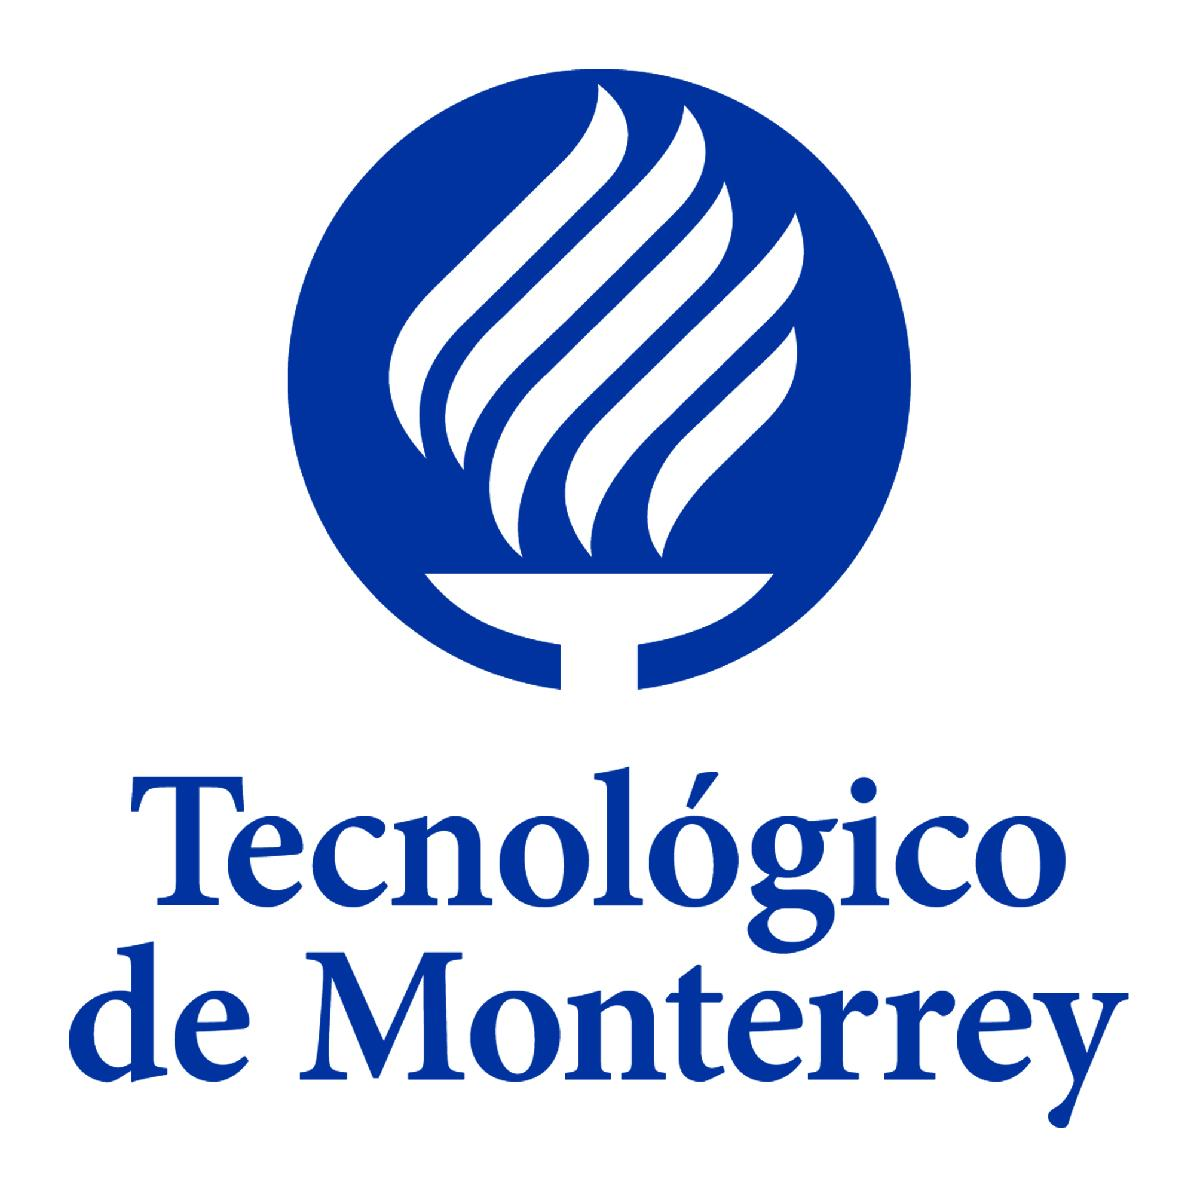 

**Simulador 2. Simulador de Alfa**

Presentado por:

Daniel Emilio Fuentes Portaluppi - A01708302

Profesor:

Ernesto Momox Beristain

F1013B Modelación computacional de sistemas eléctricos | Grupo 201

Viernes, 8 de abril del 2022

clc;
clear all;

Primero asignamos estas variables constantes, osea que no van a cambiar.

%Constantes
g = 9.81;
eps0 = 8.854e-12;

Aquí se asignan los parámetros que si van a cambiar y son los que va a asignar el usuario.

%Parametros
m = input("Introduce la masa de las cargas: " )

m = 0.2000

l = input("Introduce la longitud de la cuerda: ")

l = 1.5000

Q = input("Introduce la carga: ")

Q = 4.0000e-06

Fórmula cuando se asume que el ángulo es  pequeño (-10 grados)

alfa = rad2deg((Q^2/(16 * pi * eps0 * m * g * (l^2)))^(1/3))%Es una aproximación

alfa = 11.5274

f = @(alfa) 16 * pi * eps0 * m * g * (l^2) * sind(alfa)^2 * tand(alfa) - Q^2;

Aquí le das una función y un punto, para que empiece a buscar 0 y te devuelva alfa

alfa2 = fzero(f,alfa)

alfa2 = 11.5270

Todo el código de graficación:

Primero grafica nuestra función.

figure(1)
fplot(f)

grid
xline(0, 'k')
yline(0, 'k')
xlabel('alpha (DEG)')
hold on

Aquí le pone un título y un punto donde se ubica alfa.

title(['alfa = ' num2str(alfa2) 'º'])
plot((alfa2),f(alfa),'ro','MarkerSize',6,'LineWidth',2)
hold off


Los límites para poder notar la parte de la gráfica que nos interesa.

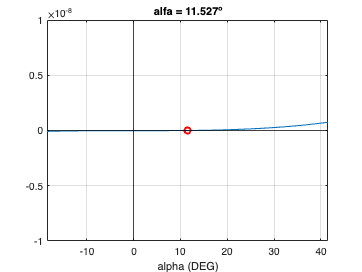

xlim([-30 + alfa2 30 + alfa2])
ylim([-1e-8 1e-8])